# Spike sorting

## 1. plot waveforms

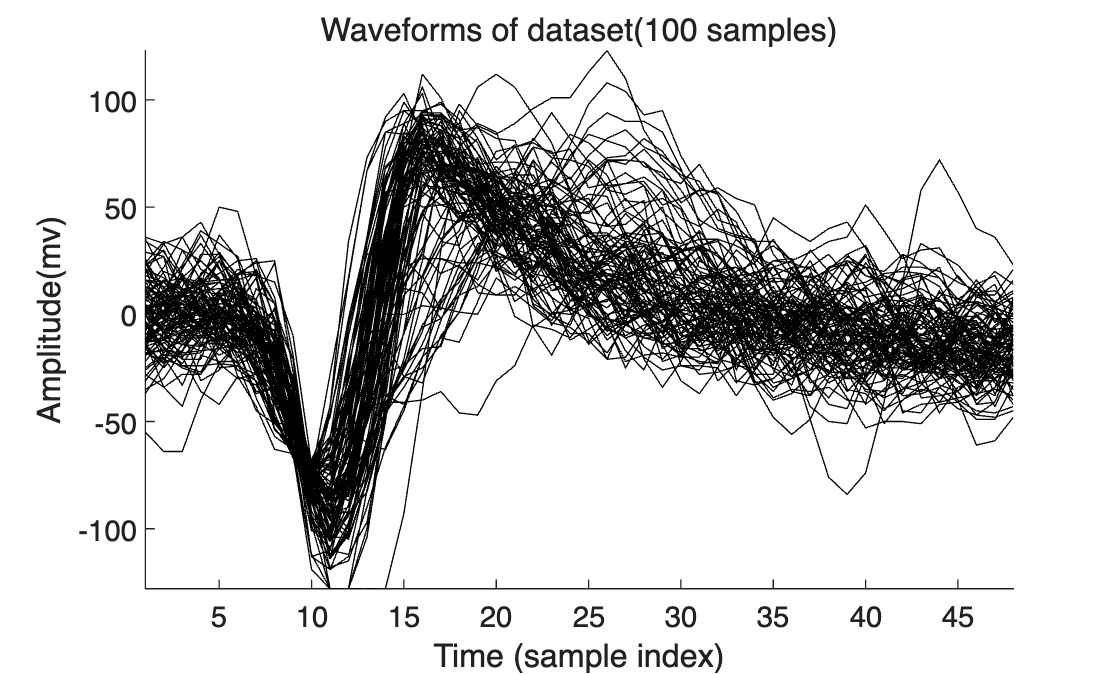

clear all;clc;
load waveforms.mat
rng(0);
idx = sort(randperm(10000, 100));
selected_data = data.wf(idx,:);
figure;
hold on;
for i = 1:size(selected_data, 1)
    plot(1:size(selected_data, 2), selected_data(i,:), 'k-');
end
xlabel('Time (sample index)');
ylabel('Amplitude(mv)');
title('Waveforms of dataset(100 samples)')
hold off;
axis tight;

## 2. PCA

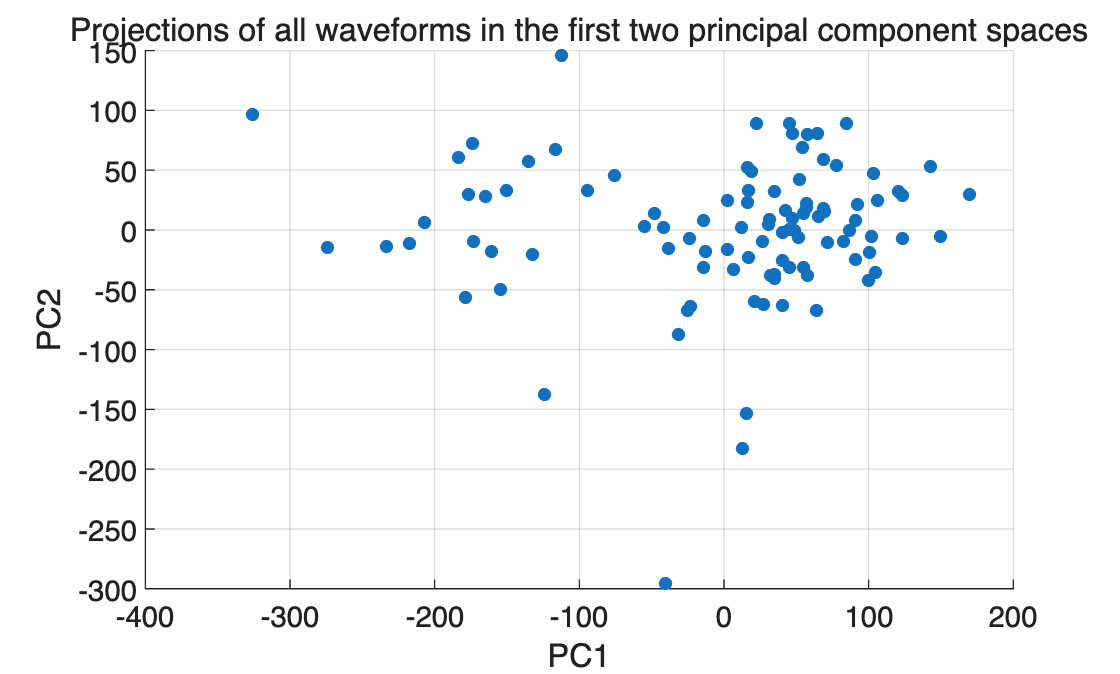

[coeff, score, latent] = pca(selected_data);

figure;
scatter(score(:,1), score(:,2), 25, 'filled');
xlabel('PC1');
ylabel('PC2');
title('Projections of all waveforms in the first two principal component spaces');
grid on;

## 3. Kmeans

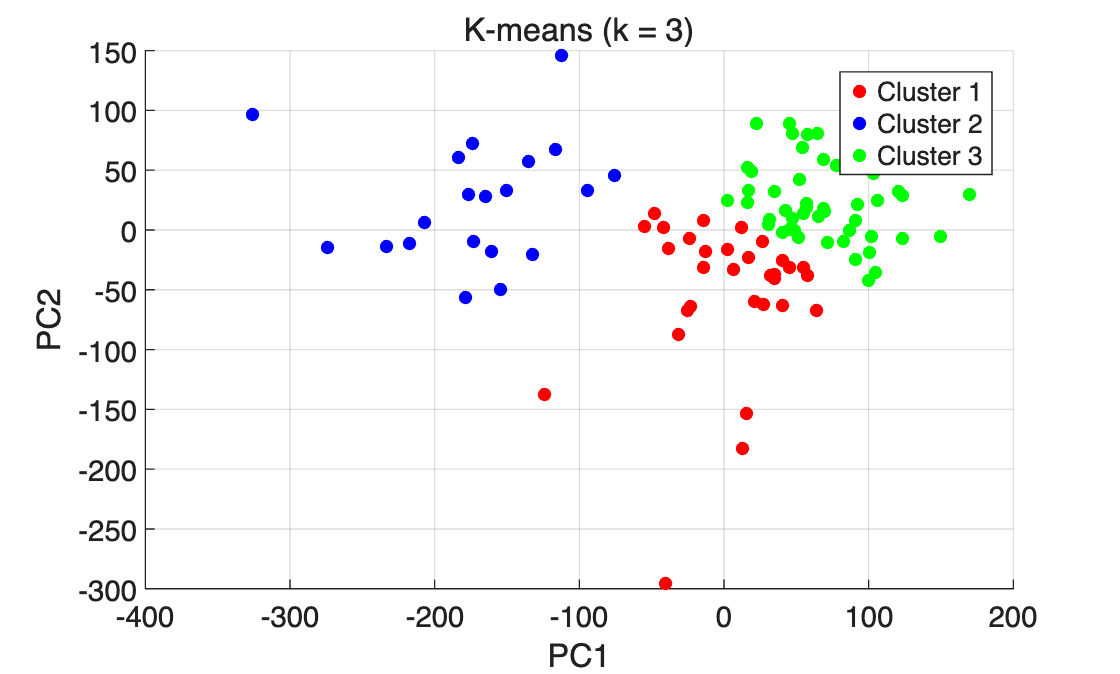

k = 3; 
[idx_k, C] = kmeans(score(:,1:2), k, 'Replicates', 10);

figure;
gscatter(score(:,1), score(:,2), idx_k, 'rbg', '.'); 

xlabel('PC1');
ylabel('PC2');
title(['K-means (k = ', num2str(k), ')']);
legend('Cluster 1', 'Cluster 2', 'Cluster 3','Location','northeast');
grid on;

## 4. plot waveform colored by cluster

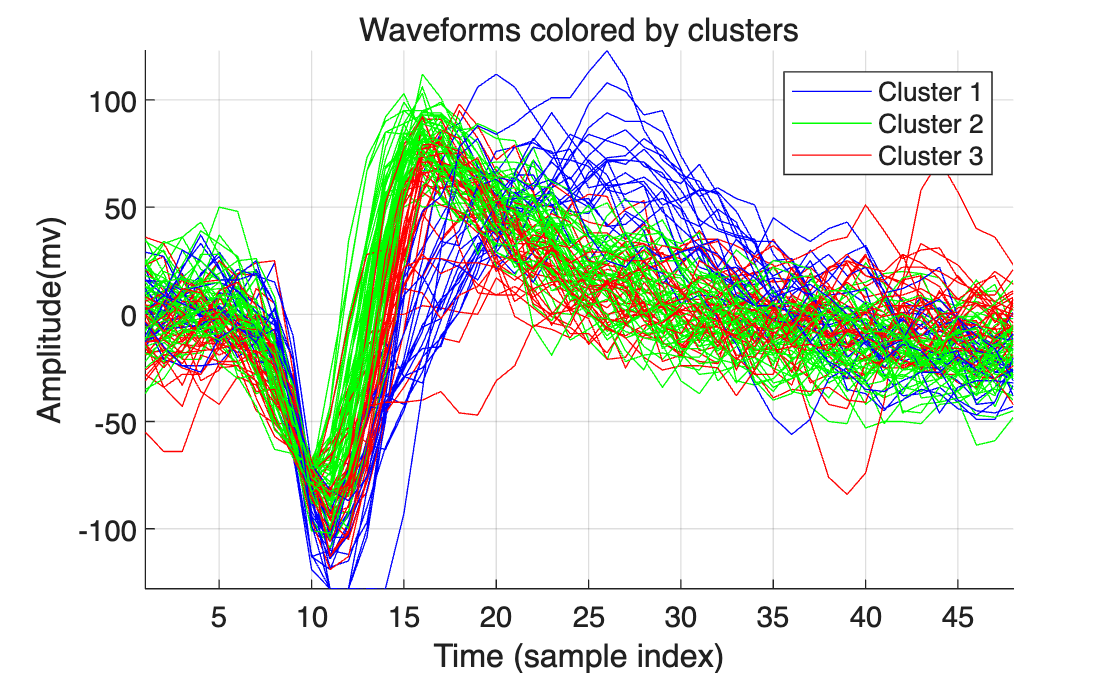

figure;
hold on;
for i = 1:size(selected_data, 1)
    if idx_k(i) == 1
        plot(1:size(selected_data, 2), selected_data(i,:), 'r-');
    elseif idx_k(i) == 2 
        plot(1:size(selected_data, 2), selected_data(i,:), 'b-');
    elseif idx_k(i) == 3 
        plot(1:size(selected_data, 2), selected_data(i,:), 'g-');
    end
end
xlabel('Time (sample index)');
ylabel('Amplitude(mv)');
title('Waveforms colored by clusters');
legend('Cluster 1', 'Cluster 2', 'Cluster 3','Location','northeast');
grid on;
axis tight;
hold off;

## 5.1 kmeans-Try initializing all the cluster centers in the same location(bad)

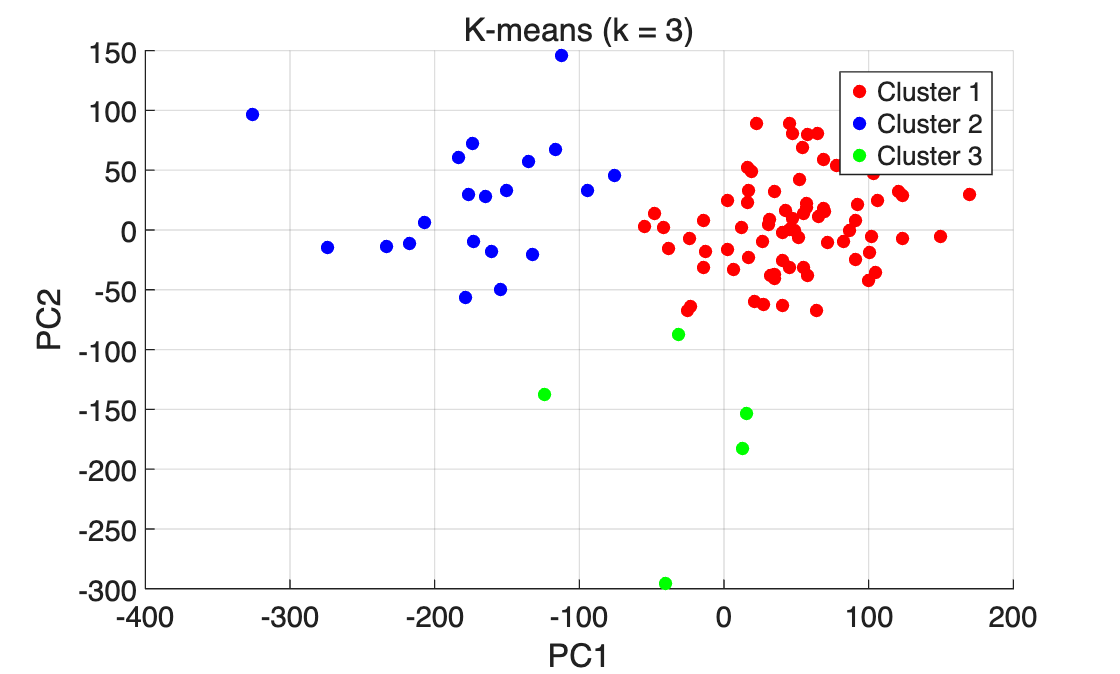

initCents = [-400, -100; -400, -100; -400, -100];
[idx_k, C] = kmeans(score(:,1:2), k, 'Start', initCents);

figure;
gscatter(score(:,1), score(:,2), idx_k, 'rbg', '.'); 
xlabel('PC1');
ylabel('PC2');
title(['K-means (k = ', num2str(k), ')']);
legend('Cluster 1', 'Cluster 2', 'Cluster 3','Location','northeast');
grid on;

## 5.2 kmeans-Try initializing all the cluster centers in the same location(good performance)

initCents = [0, 50; -200, 50; 100, 100];
[idx_k, C] = kmeans(score(:,1:2), k, 'Start', initCents);

figure;
gscatter(score(:,1), score(:,2), idx_k, 'rbg', '.');
xlabel('PC1');
ylabel('PC2');
title(['K-means (k = ', num2str(k), ')']);
legend('Cluster 1', 'Cluster 2', 'Cluster 3','Location','northeast');
grid on;

## 6. plot first three PCs

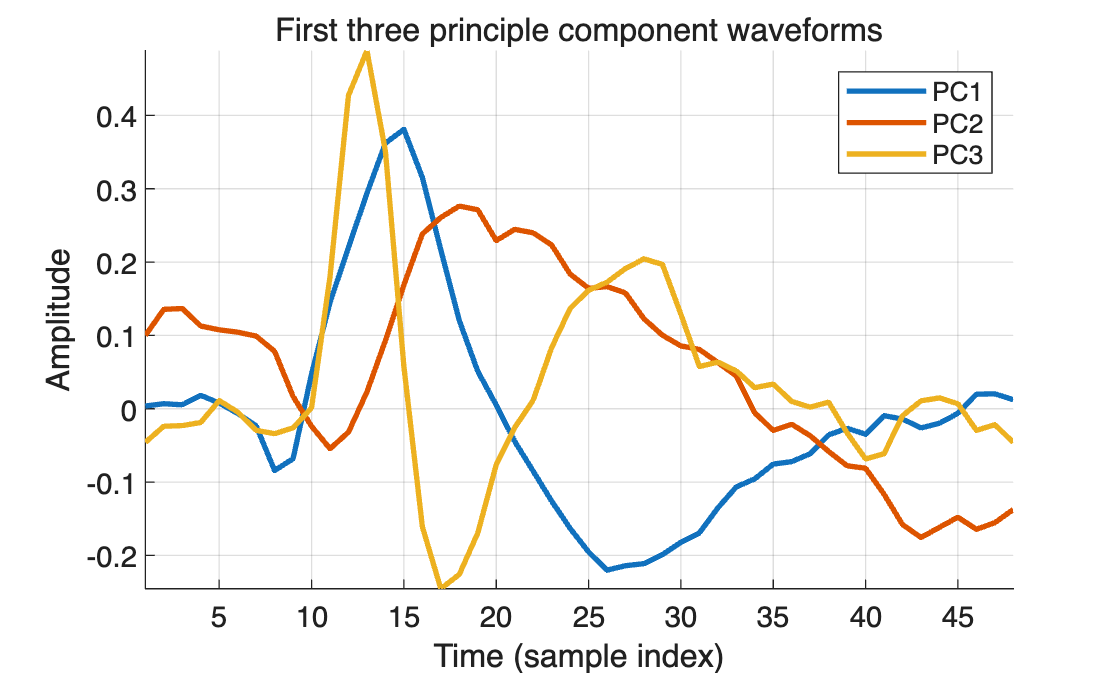

figure;
hold on
for k = 1:3
    plot(coeff(:,k), 'LineWidth', 2);
end
hold off
xlabel('Time (sample index)');
ylabel('Amplitude');
legend('PC1', 'PC2', 'PC3','Location','northeast');
title('First three principle component waveforms');
axis tight;
grid on;

## 7. eigenspectrum

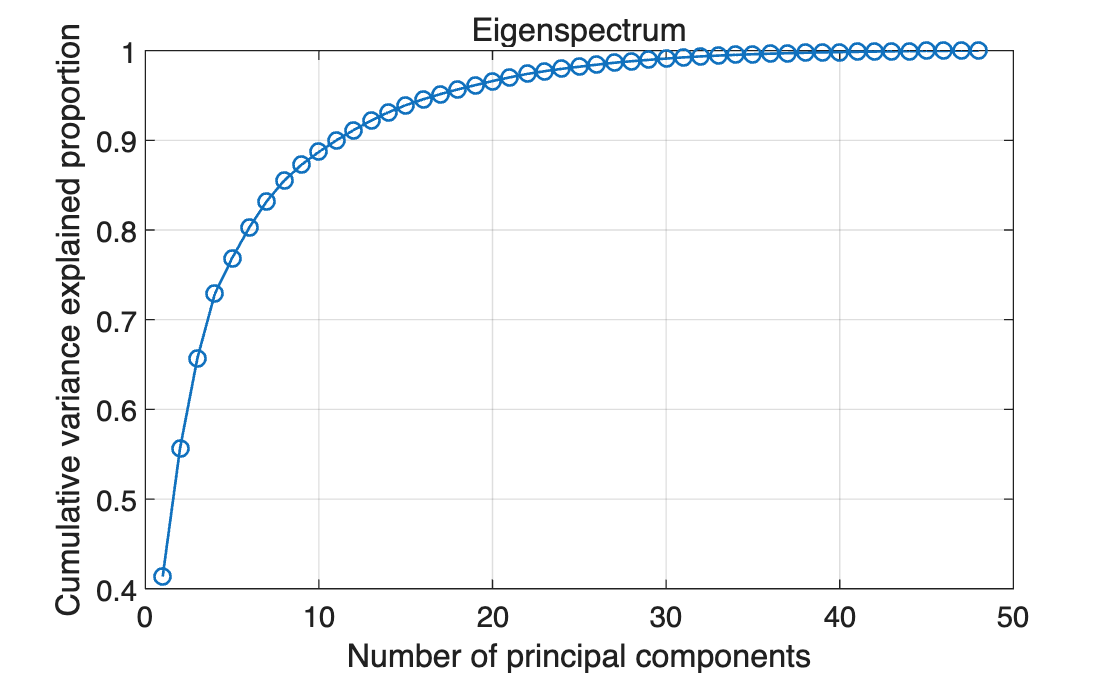

cumvar = cumsum(latent) / sum(latent); 
figure;
plot(1:length(latent), cumvar, '-o', 'LineWidth', 1);
xlabel('Number of principal components');
ylabel('Cumulative variance explained proportion');
title('Eigenspectrum');
grid on;

## 8. raster plot

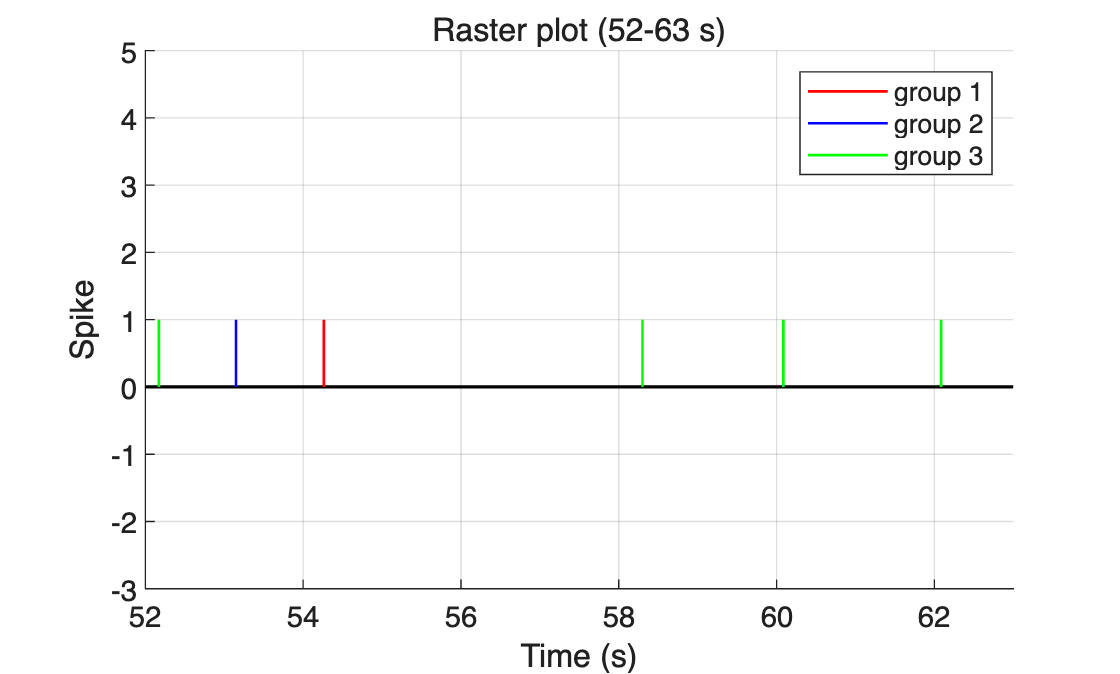

spike_times = data.stamps(idx);
idx_stamps = find(spike_times>=52 & spike_times<=63);
spike_times = spike_times(idx_stamps);
spike_k = idx_k(idx_stamps);

ymin = 0; ymax = 1;
figure;
hold on;
plot([52 63], [0 0], 'k-', 'LineWidth', 1.2);
h = zeros(1,3);
for i = 1:length(spike_times)
    if spike_k(i)==1
        if h(1)==0
            h(1) = plot([spike_times(i),spike_times(i)], [ymin,ymax], 'r', 'LineWidth', 1);
        else
            plot([spike_times(i),spike_times(i)], [ymin,ymax], 'r', 'LineWidth', 1);
        end
    elseif spike_k(i)==2
        if h(2)==0
            h(2) = plot([spike_times(i),spike_times(i)], [ymin,ymax], 'b', 'LineWidth', 1);
        else
            plot([spike_times(i),spike_times(i)], [ymin,ymax], 'b', 'LineWidth', 1);
        end
    elseif spike_k(i)==3
        if h(3)==0
            h(3) = plot([spike_times(i),spike_times(i)], [ymin,ymax], 'g', 'LineWidth', 1);
        else
            plot([spike_times(i),spike_times(i)], [ymin,ymax], 'g', 'LineWidth', 1);
        end
    end
end
legend(h, {'group 1','group 2','group 3'},'Location','northeast');
xlabel('Time (s)');
xlim([52 63])
ylabel('Spike');
ylim([-3 5]);
grid on;
title('Raster plot (52-63 s)');
hold off;

## 9. ISI histogram

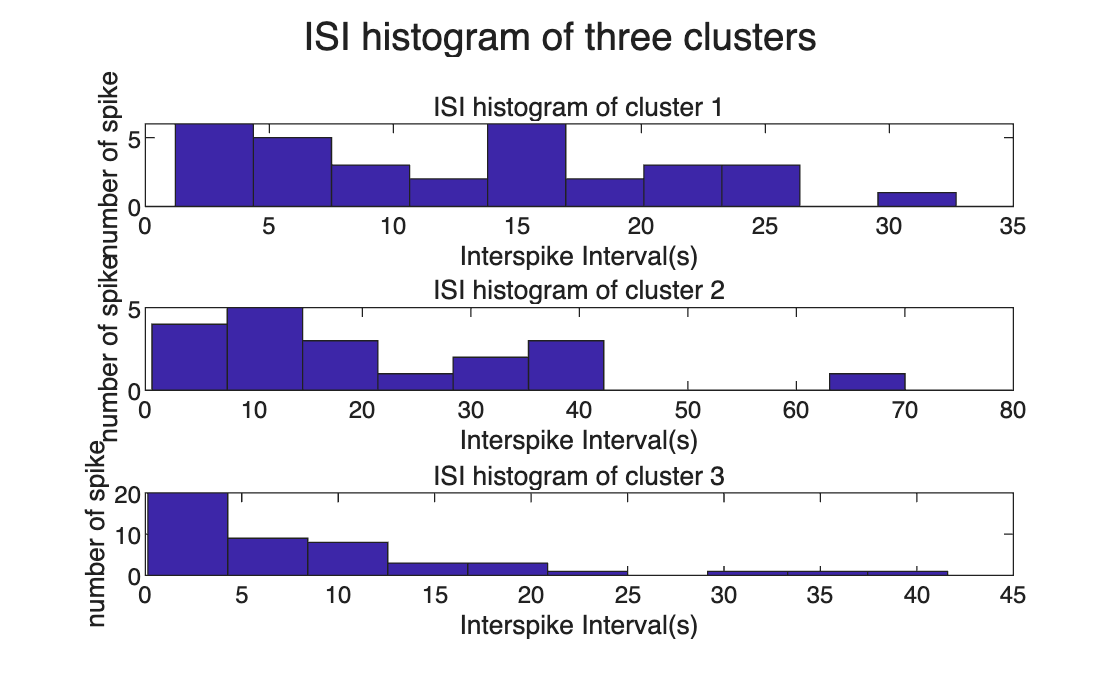

spike_times = data.stamps(idx);

cluster_1_stamps = find(idx_k == 1);
cluster_1_stamps = spike_times(cluster_1_stamps);
diff_cluster_1 = diff(cluster_1_stamps);

cluster_2_stamps = find(idx_k == 2);
cluster_2_stamps = spike_times(cluster_2_stamps);
diff_cluster_2 = diff(cluster_2_stamps);

cluster_3_stamps = find(idx_k == 3);
cluster_3_stamps = spike_times(cluster_3_stamps);
diff_cluster_3 = diff(cluster_3_stamps);

subplot(3,1,1)
hist(diff_cluster_1)
xlabel('Interspike Interval(s)')
ylabel('number of spike')
title('ISI histogram of cluster 1')
subplot(3,1,2)
hist(diff_cluster_2)
xlabel('Interspike Interval(s)')
ylabel('number of spike')
title('ISI histogram of cluster 2')
subplot(3,1,3)
hist(diff_cluster_3)
xlabel('Interspike Interval(s)')
ylabel('number of spike')
title('ISI histogram of cluster 3')
sgtitle('ISI histogram of three clusters')